%calculating the mean first passage time using Gillespie simulations 
%to investigate the effect of invader toehold length on RNA/DNA toehold
%exchange kinetics including spontaneous incumbent dissociation

b = 20 %define branch migration domain length 

b = 20

g2 = 2 %define incumbent toehold length

g2 = 2

bg2 = b + g2 %define branch migration domain + incumbent toehold length

bg2 = 22


R = 1.987/1000 % universal gas constant in kcal/K/mol

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGrd = -1*R*temp

dGrd = -0.5924

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

N = 10 %number of simulations

N = 10

avr_first_pass_time = zeros(1,15)

avr_first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_first_pass_time = zeros(15, N)

ind_first_pass_time =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


k_eff = zeros(1, 15)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_k_eff = zeros(15, N)

ind_k_eff =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


std_err_fpt = zeros(1, 15)

std_err_fpt =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


std_err_k_eff = zeros(1, 15)

std_err_k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


std_err_log_k = zeros(1,15)

std_err_log_k =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through invader toehold length 
for g = 1:15
    
    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp((dGbp + dGrd)/(R*temp))
    k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp((dGbp + dGrd)/(R*temp))
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cr = k_bp * exp(-(dGbm - dGrd)/(R*temp))
    k_DC = k_bp * exp(-(dGbm + dGp - dGrd)/(R*temp))
    k_DEij = k_bp * exp(dGbp/(R*temp));
    k_DEji = k_bp;
    k_EF = k_bp * exp(dGbp/(R*temp));
    k_FE = 0
    k_FF = 1   
    
    
    first_pass_time = zeros(1,N)
    
    %create arrays of forward and reverse transition rates
    if g == 1
        Kf = [k_AB1, k_C1f, repmat(k_Cf, [1, b-1]), repmat(k_DEij, [1, g2-1]), k_EF, k_FF]
        Kb = [k_AA, k_B1A, repmat(k_Cr, [1 b-1]), k_DC, repmat(k_DEji, [1, g2-1]), k_FE]
        
        %define spontaneous incumbent dissociation rate
        Koff = [0, 0]; 
        for n = bg2-1:-1:g2+1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g2+1])])
    else
        Kf = [k_AB1, k_BC1ij, repmat(k_BC1ij, [1, g-2]), k_C1f, repmat(k_Cf, [1, b-1]), repmat(k_DEij, [1, g2-1]), k_EF, k_FF]
        Kb = [k_AA, k_B1A, repmat(k_BC1ji, [1, g-2]), k_BC1ji, repmat(k_Cr, [1, b-1]), k_DC, repmat(k_DEji, [1, g2-1]), k_FE]
            
        %define spontaneous incumbent dissociation rate
        Koff = [repmat(0, [1, g+1])];
        for n = bg2-1:-1:g2+1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g2+1])])      
    end
    
    totalrate = Kf + Kb + Koff; %define total rate
    Pf = Kf./totalrate; %define probability of forward transition
    Poff = Koff./totalrate; %define probability of spontaneous incumbent dissociation
    Pb = 1- (Pf + Poff); %define probability of reverse transition
    %loop through simulations
    for n = 1:N 
        state = 1; %initial state
        t = 0; %initial time
        %restrict to possible states
        while (state >=1 && state < (2 + g + b + g2)) 
            t = t - (1/totalrate(state))*log(rand()); %calculate time for transition
            prob = rand();
            %select transition
            if prob <= Pf(state) 
                state = state +1; %update state forward
            elseif prob > Pf(state) && prob < Pf (state) + Poff(state)
                state = 2 + g + b + g2; %update state for spontaneous incumbent dissociation
            else 
                state = state -1; %update state backwards
            end
        end
        first_pass_time(n) =  t; 
        ind_first_pass_time(g,n) = first_pass_time(n);
        ind_k_eff(g,n) = 1/(first_pass_time(n)*(5*10^-8));
    end
    std_err_fpt(g) = std(ind_first_pass_time(g, :))/sqrt(N); %calculate standard error
    std_err_k_eff(g) = std(ind_k_eff(g, :))/sqrt(N);
    std_err_log_k(g) = std(log10(ind_k_eff(g,:))/sqrt(N));
    avr_first_pass_time(g) = mean(first_pass_time) %calculate average first passage time
    k_eff(g) = 1/(mean(first_pass_time)*(5*10^-8)) %calculate effective rate constant
end

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+06 *

    0.0000    0.0009    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    0.0000


Kb = 	1.0e+07 *

         0    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff = 	1.0e+04 *

         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time = 	1.0e+04 *

    1.1847         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    1.6882         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff = 	1.0e+04 *

         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time = 	1.0e+04 *

    1.1847    0.0726         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+04 *

    0.1688    2.7546         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time = 	1.0e+04 *

    1.1847    0.0726    0.0016         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

    0.0017    0.0275    1.2682         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time = 	1.0e+04 *

    1.1847    0.0726    0.0016    0.0007         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

    0.0017    0.0275    1.2682    2.7322         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time = 	1.0e+04 *

    1.1847    0.0726    0.0016    0.0007    0.0005         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

    0.0017    0.0275    1.2682    2.7322    4.4278         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.1598    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time = 	1.0e+04 *

    1.1847    0.0726    0.0016    0.0007    0.0005    0.0005         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

    0.0017    0.0275    1.2682    2.7322    4.4278    3.7318         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.1598    0.1598    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time = 	1.0e+04 *

    1.1847    0.0726    0.0016    0.0007    0.0005    0.0005    0.0004         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

    0.0017    0.0275    1.2682    2.7322    4.4278    3.7318    5.7099         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.1598    0.1598    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000


Koff =          0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0


avr_first_pass_time =     1.1847    0.0726    0.0016    0.0007    0.0005    0.0005    0.0004    0.0005         0         0         0         0         0         0         0


k_eff =     0.0017    0.0275    1.2682    2.7322    4.4278    3.7318    5.7099    3.7483         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345


Kb =          0    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0003


Koff =          0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0


avr_first_pass_time =     1.1847    0.0726    0.0016    0.0007    0.0005    0.0005    0.0004    0.0005    0.0008         0         0         0         0         0         0


k_eff =     0.0017    0.0275    1.2682    2.7322    4.4278    3.7318    5.7099    3.7483    2.4822         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127


avr_first_pass_time =     1.1847    0.0726    0.0016    0.0007    0.0005    0.0005    0.0004    0.0005    0.0008    0.0007         0         0         0         0         0


k_eff =     0.0017    0.0275    1.2682    2.7322    4.4278    3.7318    5.7099    3.7483    2.4822    2.8536         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0012    0.0147    0.1821    2.2631


avr_first_pass_time =     1.1847    0.0726    0.0016    0.0007    0.0005    0.0005    0.0004    0.0005    0.0008    0.0007    0.0003         0         0         0         0


k_eff =     0.0017    0.0275    1.2682    2.7322    4.4278    3.7318    5.7099    3.7483    2.4822    2.8536    6.4098         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888


avr_first_pass_time =     1.1847    0.0726    0.0016    0.0007    0.0005    0.0005    0.0004    0.0005    0.0008    0.0007    0.0003    0.0007         0         0         0


k_eff =     0.0017    0.0275    1.2682    2.7322    4.4278    3.7318    5.7099    3.7483    2.4822    2.8536    6.4098    2.8662         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508


avr_first_pass_time =     1.1847    0.0726    0.0016    0.0007    0.0005    0.0005    0.0004    0.0005    0.0008    0.0007    0.0003    0.0007    0.0007         0         0


k_eff =     0.0017    0.0275    1.2682    2.7322    4.4278    3.7318    5.7099    3.7483    2.4822    2.8536    6.4098    2.8662    2.9071         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788


avr_first_pass_time =     1.1847    0.0726    0.0016    0.0007    0.0005    0.0005    0.0004    0.0005    0.0008    0.0007    0.0003    0.0007    0.0007    0.0008         0


k_eff =     0.0017    0.0275    1.2682    2.7322    4.4278    3.7318    5.7099    3.7483    2.4822    2.8536    6.4098    2.8662    2.9071    2.5333         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948


avr_first_pass_time =     1.1847    0.0726    0.0016    0.0007    0.0005    0.0005    0.0004    0.0005    0.0008    0.0007    0.0003    0.0007    0.0007    0.0008    0.0009


k_eff =     0.0017    0.0275    1.2682    2.7322    4.4278    3.7318    5.7099    3.7483    2.4822    2.8536    6.4098    2.8662    2.9071    2.5333    2.1634


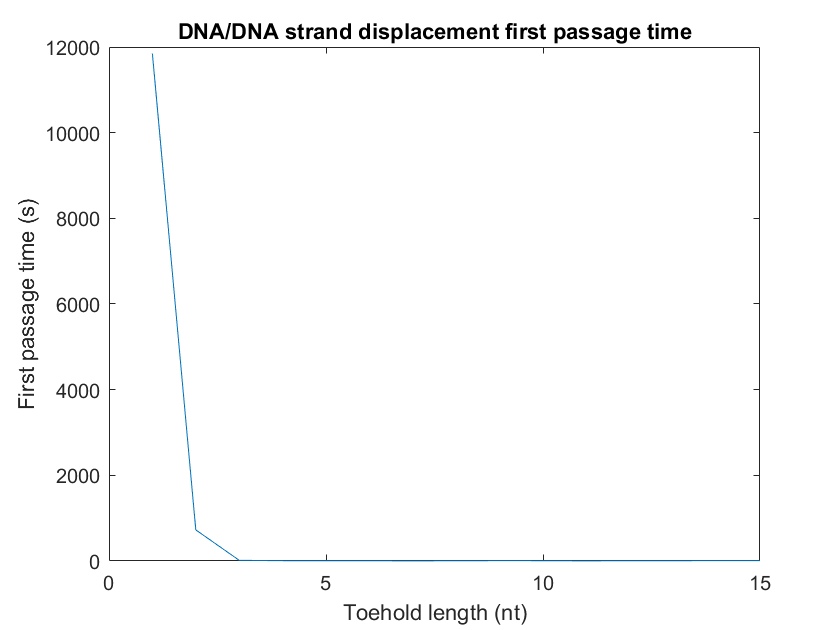

plot(1:15, avr_first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

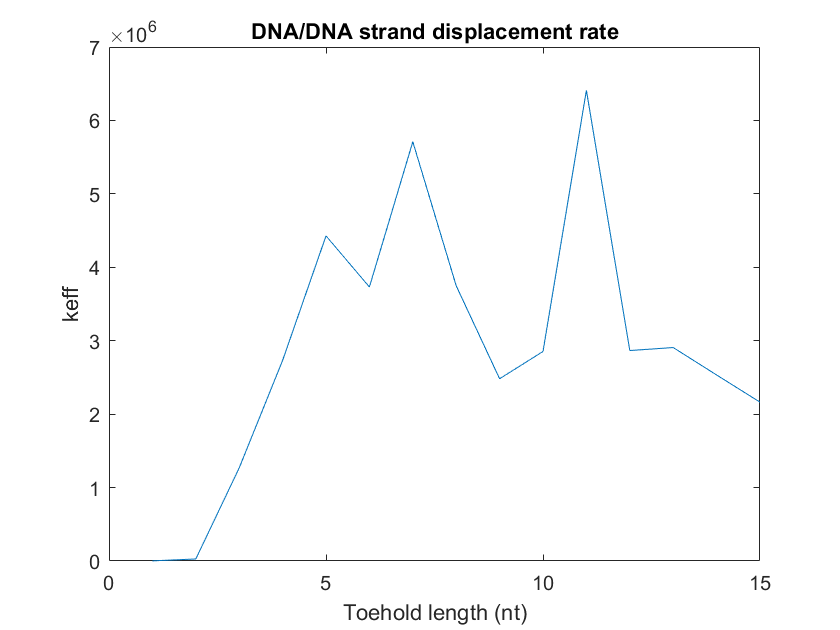


plot(1:15, k_eff)
ylabel('keff')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement rate')

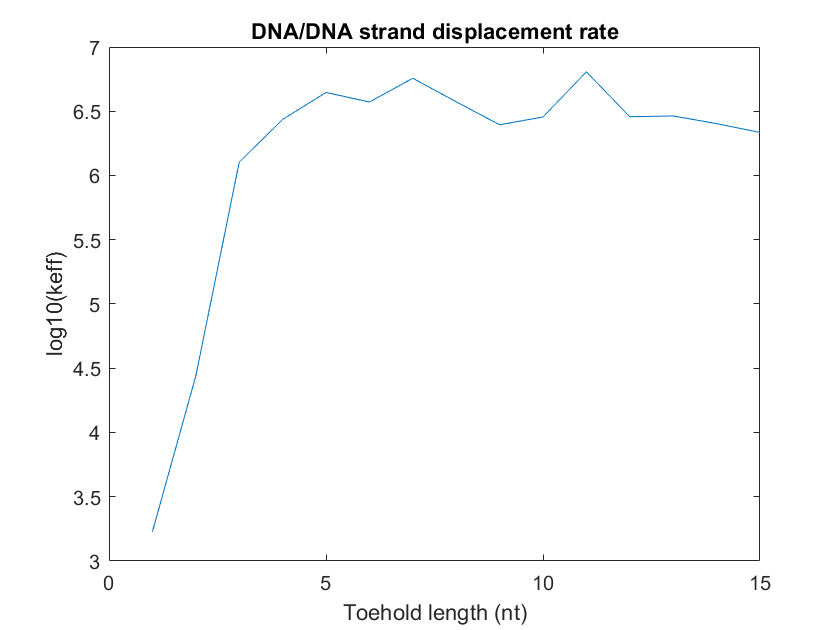


plot(1:15, log10(k_eff))
ylabel('log10(keff)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement rate')

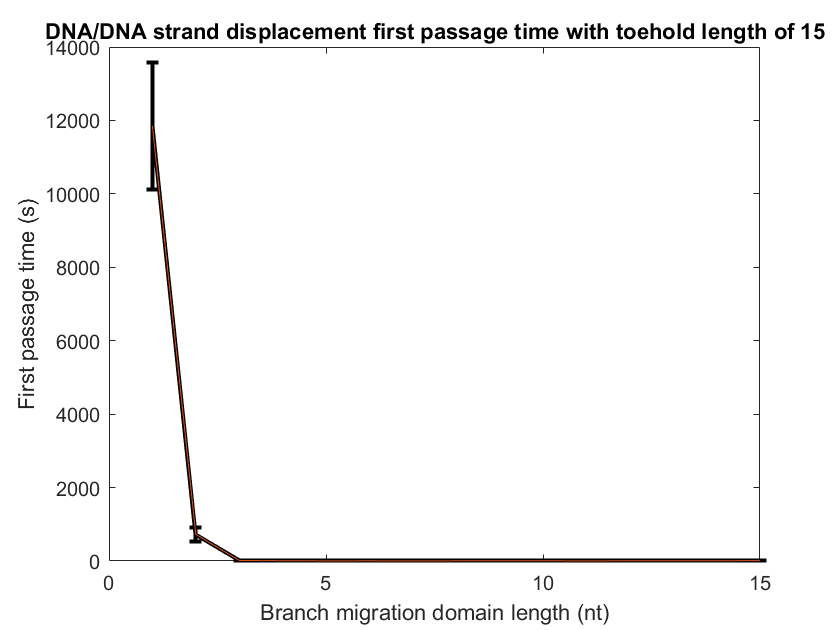


errorbar(1:15, avr_first_pass_time, std_err_fpt , 'k', 'linewidth', 2)
hold on
plot(1:15, avr_first_pass_time, 'linewidth', 0.5)
xlabel('Branch migration domain length (nt)')
ylabel('First passage time (s)')
title('DNA/DNA strand displacement first passage time with toehold length of ' + string(g))

hold off

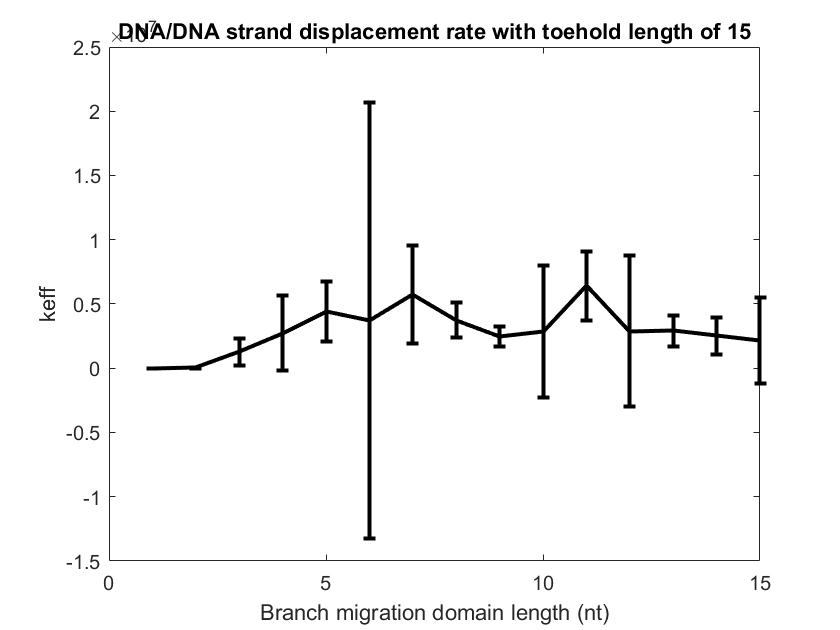


errorbar(1:15, k_eff, std_err_k_eff, 'k', 'linewidth', 2)
xlabel('Branch migration domain length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate with toehold length of ' + string(g))
hold off

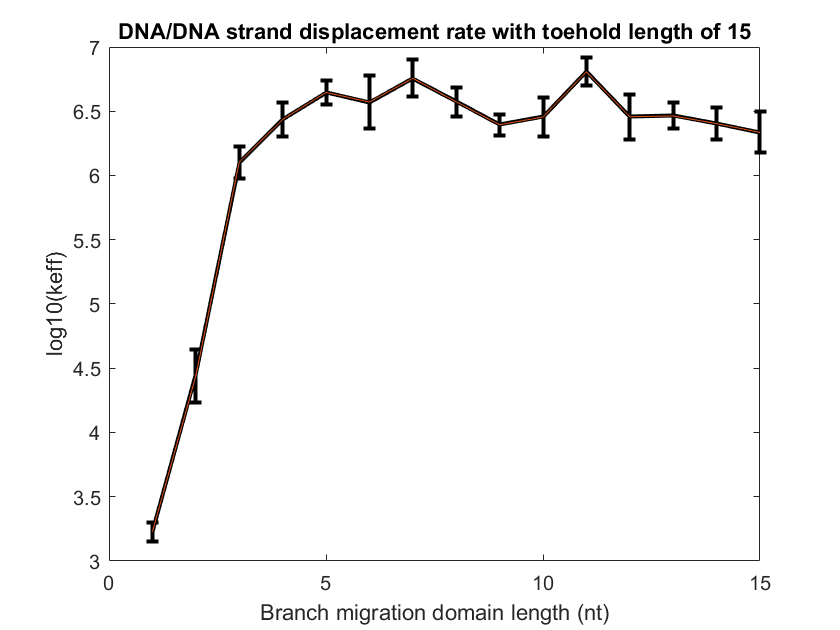


errorbar(1:15, log10(k_eff), std_err_log_k, 'k', 'linewidth', 2)
hold on
plot(1:15, log10(k_eff), '', 'linewidth', 0.5)
xlabel('Branch migration domain length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate with toehold length of ' + string(g))
hold off